colobj = roomspec();

resolution = 20;
binary_map = colobj2binary_map(colobj, resolution);

binary_map_inflated = binaryOccupancyMap(binary_map)

binary_map_inflated =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 20
               GridSize: [200 200]
           XLocalLimits: [0 10]
           YLocalLimits: [0 10]
           XWorldLimits: [0 10]
           YWorldLimits: [0 10]


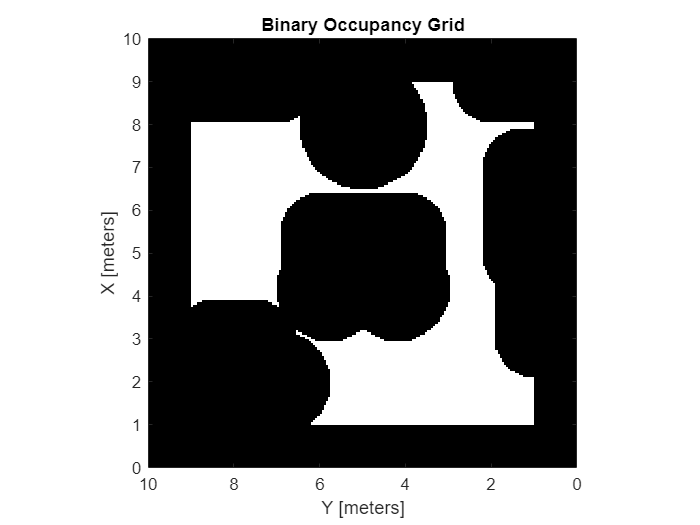


inflate(binary_map_inflated, 0.9)
show(binary_map_inflated)
view(-90,90);


%p_start = rand_pt_in_map(binary_map_inflated);
%p_end = rand_pt_in_map(binary_map_inflated);
p_start = [2 1.5]

p_start =     2.0000    1.5000


p_end = [8 8]

p_end =      8     8


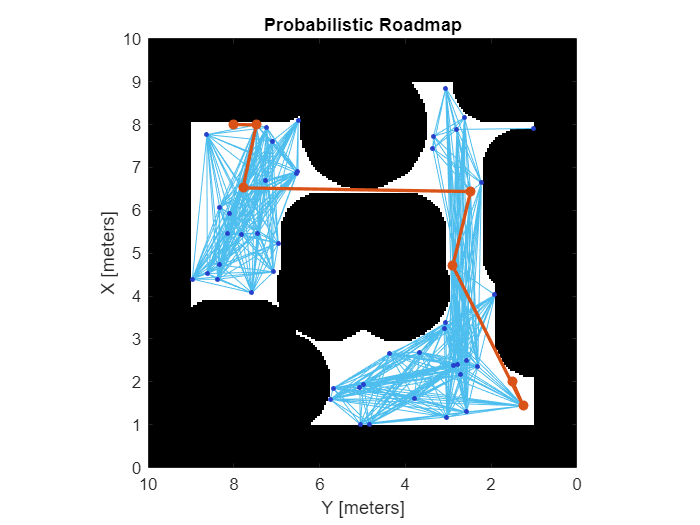



prm = mobileRobotPRM(binary_map_inflated);
xy = findpath(prm,p_start,p_end);

show(prm)
view(-90,90);

% generate trajectory

[lambda,~,~,~,~] = trapveltraj([0 dists(end)],400)

lambda =          0    0.0002    0.0007    0.0015    0.0027    0.0042    0.0060    0.0082    0.0107    0.0136    0.0168    0.0203    0.0241    0.0283    0.0328    0.0377    0.0429    0.0484    0.0543    0.0605    0.0670    0.0739    0.0811    0.0886    0.0965    0.1047    0.1133    0.1221    0.1314    0.1409    0.1508    0.1610    0.1716    0.1825    0.1937    0.2052    0.2171    0.2294    0.2419    0.2548    0.2681    0.2816    0.2956    0.3098    0.3244    0.3393    0.3545    0.3701    0.3860    0.4023


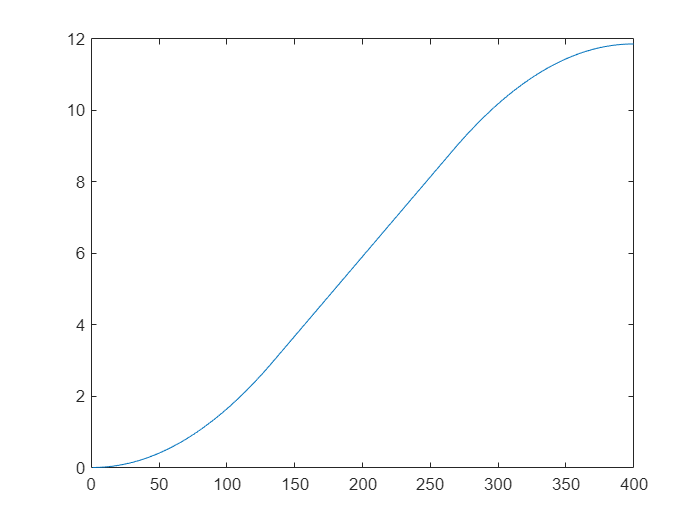

plot(lambda)


dists = [0 cumsum(vecnorm(diff(xy)'))]

dists =          0    0.6143    4.2674    6.0523   11.3607   12.8624   13.3851


traj = interp1(dists,xy,lambda);
traj=traj';


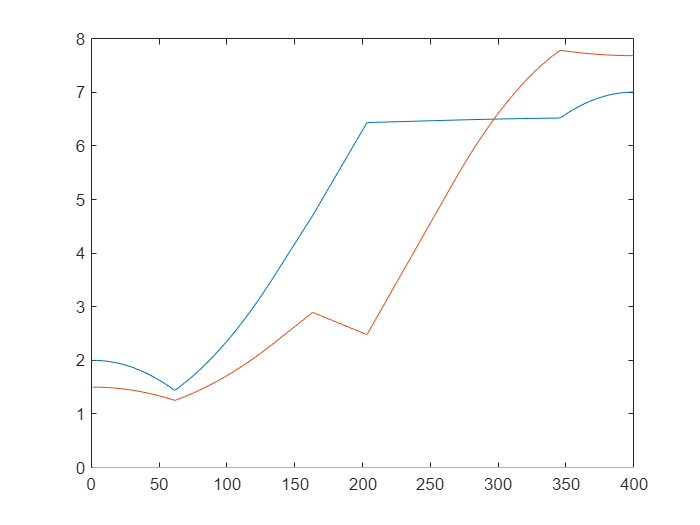


plot(traj')

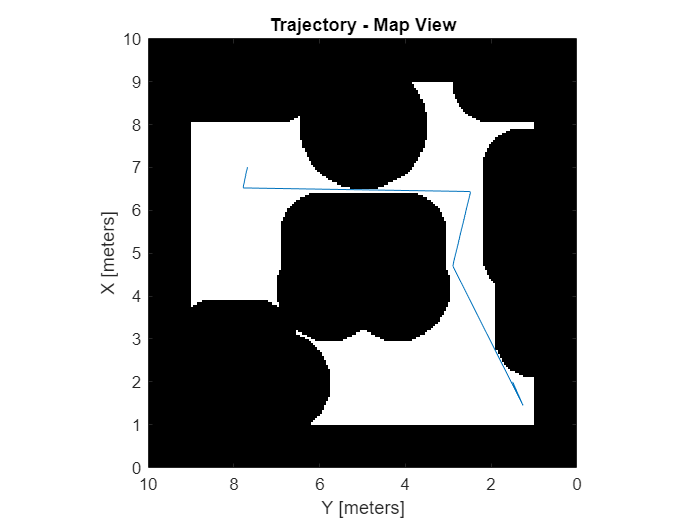

show(binary_map_inflated); hold on
plot(traj(1,:),traj(2,:)); hold off
view(-90,90);
title("Trajectory - Map View")

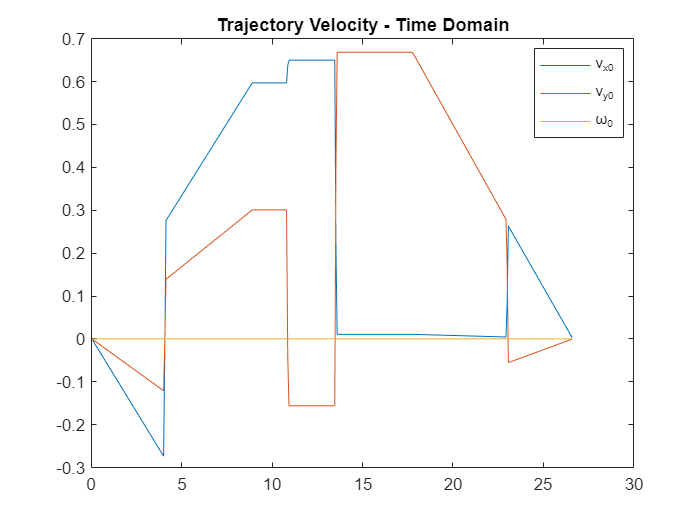


plot((1:length(traj)-1)'*1/15, diff(traj')*15)
title("Trajectory Velocity - Time Domain")
legend(["v_{x0}", "v_{y0}", "\omega_0"], Location="best")

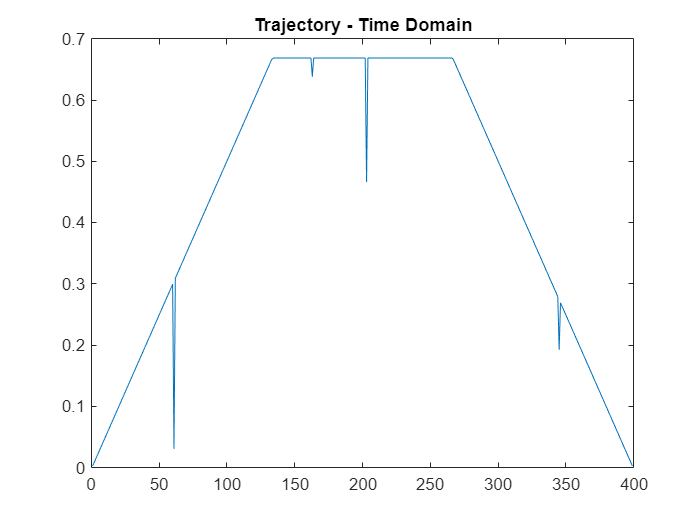



traj(3,:) = 0;
traj_vel(3,:) = 0;
plot(vecnorm(diff(traj')')*15)
title("Trajectory - Time Domain")